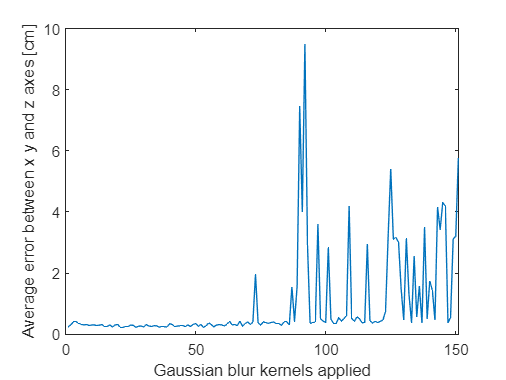

clear;
clc;


BlurTest = importdata("BlurTest.csv");
BlurTestBinary = importdata("BlurTest_binary.csv");
BlurTestAvg = zeros(1,151);
BlurTestElbow = zeros(1,151);
for i = 1:151
    BlurTestAvg(i) = mean(BlurTest(i,:));
end
%x = linspace(0,300,151)
plot(BlurTestAvg*100)
ylabel('Average error between x y and z axes [cm]')
xlabel('Gaussian blur kernels applied')

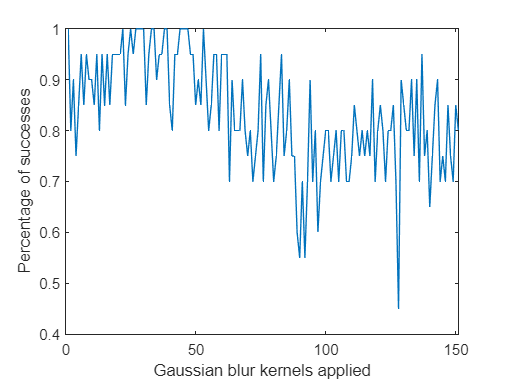

%title('Average error on x,y and z axes with respect to added noise (gaussian)')

for i = 1:151
    BlurTestElbow(i) = sum(BlurTestBinary(i,:)) / 20;
end
plot(BlurTestElbow)
ylabel('Percentage of successes')
xlabel('Gaussian blur kernels applied')

%title('Percentage of successes with respect to added noise (gaussian)')



SPTest = importdata("SPTest.csv");
SPTestBinary = importdata("SPTest_binary.csv");
SPTestAvg = zeros(1,101);
SPTestElbow = zeros(1,101);
for i = 1:101
    SPTestAvg(i) = mean(SPTest(i,:));
end
x = linspace(0,100,101)

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


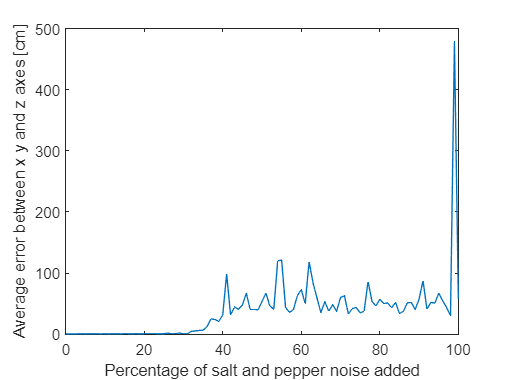

plot(x, SPTestAvg*100)
ylabel('Average error between x y and z axes [cm]')
xlabel('Percentage of salt and pepper noise added')

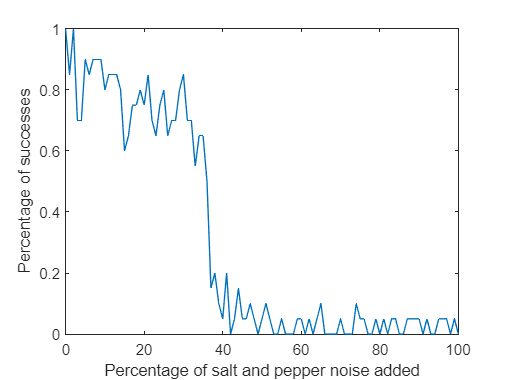

for i = 1:101
    SPTestElbow(i) = sum(SPTestBinary(i,:)) / 20;
end
plot(x, SPTestElbow)
ylabel('Percentage of successes')
xlabel('Percentage of salt and pepper noise added')



BlurSPTest = importdata("BlurSPTest.csv");
BlurSPTestBinary = importdata("BlurSPTest_binary.csv");
BlurSPTestAvg = zeros(1,51);
BlurSPTestElbow = zeros(1,51);
for i = 1:51
    BlurSPTestAvg(i) = mean(BlurSPTest(i,:));
end
x = linspace(0,100,51)

x =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


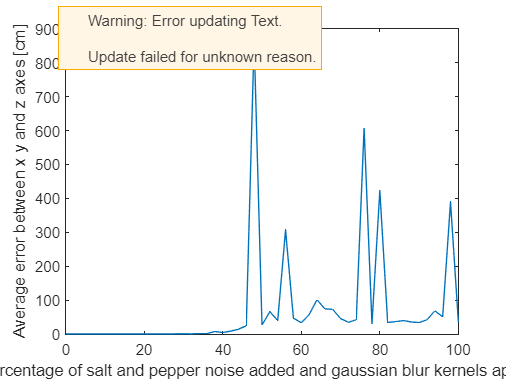

plot(x, BlurSPTestAvg*100)
ylabel('Average error between x y and z axes [cm]')
xlabel('Percentage of salt and pepper noise added and gaussian blur kernels applied')

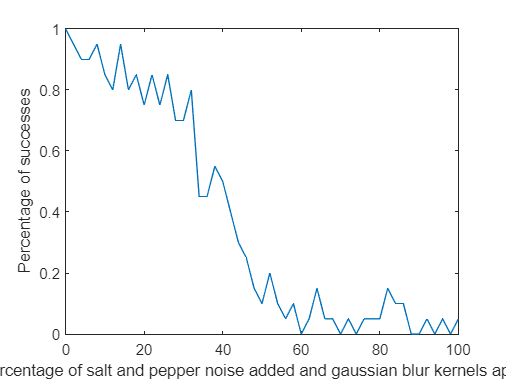

for i = 1:51
    BlurSPTestElbow(i) = sum(BlurSPTestBinary(i,:)) / 20;
end
plot(x, BlurSPTestElbow)
ylabel('Percentage of successes')
xlabel('Percentage of salt and pepper noise added and gaussian blur kernels applied')

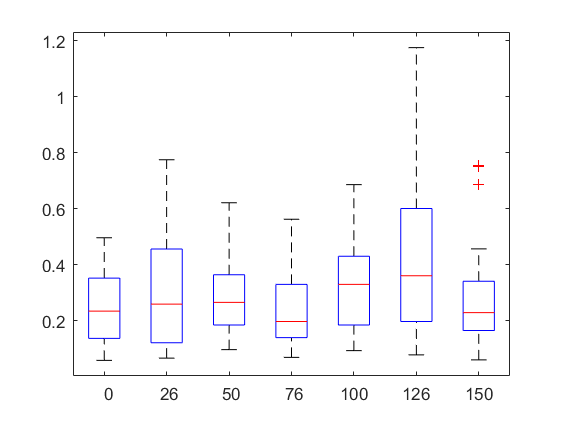





% BOXPLOTS

% 0, 26, 50, 76, 100, 126, 150
boxplot([BlurTest(1,:)'*100, BlurTest(13,:)'*100, BlurTest(25,:)'*100, BlurTest(38,:)'*100, BlurTest(50,:)'*100, BlurTest(63,:)'*100, BlurTest(75,:)'*100],'Labels',{0, 26, 50, 76, 100, 126, 150})

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



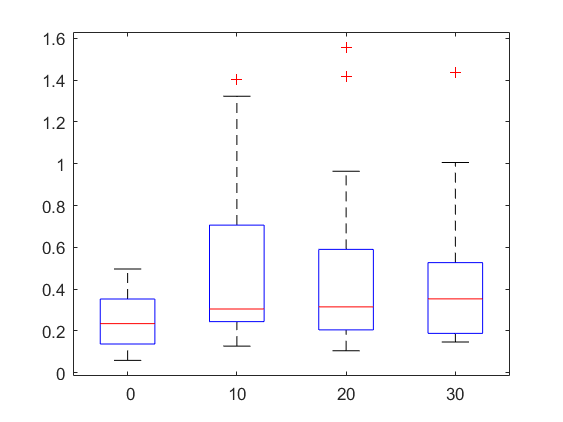


% 0, 10, 20, 30, 40, 50, 60
boxplot([SPTest(1,:)'*100, SPTest(11,:)'*100, SPTest(21,:)'*100, SPTest(31,:)'*100],'Labels',{0, 10, 20, 30})